# Lyapunov function demonstration

In real life, we construct Lyapunov function to a specific system. In this script, only with the intention of demonstration, we generate a system to a specific Lyapunov function.

## Lyapunov function $V(x)$

syms alpha t x y real
r = [x;y]

Consider the following Lyapunov function

V = alpha - (x + 1 + alpha) * exp(-x - 1 - alpha) / (1 + exp(-x - 1 - alpha)) + sqrt(y^2 + 1) / 2 - 1/2

$$V = \alpha +\frac{\sqrt{y^{2}+1}}{2}-\frac{{\mathrm{e}}^{-\alpha -x-1}\,\left(\alpha +x+1\right)}{{\mathrm{e}}^{-\alpha -x-1}+1}-\frac{1}{2}$$

## Vector field $f(x)$

gradV = jacobian(V,r);
f = [ gradV(2) ; -gradV(1) ] + diag([-0.03 -0.03])*r

$$f = \begin{array}{l} \left(\begin{array}{c} \frac{y}{2\,\sqrt{y^{2}+1}}-\frac{3\,x}{100}\\ \frac{{\mathrm{e}}^{-\alpha -x-1}}{\sigma_{1}}-\frac{3\,y}{100}-\frac{{\mathrm{e}}^{-\alpha -x-1}\,\left(\alpha +x+1\right)}{\sigma_{1}}+\frac{{\mathrm{e}}^{-2\,\alpha -2\,x-2}\,\left(\alpha +x+1\right)}{{\sigma_{1}}^{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-\alpha -x-1}+1 \end{array}$$

The value of $\alpha$ is the value of a very special function in $e^{-1}$

alpha = lambertw(exp(-1));

We substitute the value of alpha into the functions

V_sym = subs(V);
f_sym = subs(f);

We generate Matlab typed function handles

V_fh = matlabFunction(V_sym, 'vars', r);
f_ode = matlabFunction(f_sym, 'vars', {t r});
f1_fh = matlabFunction(f_sym(1), 'vars', r);
f2_fh = matlabFunction(f_sym(2), 'vars', r);

Simulate the system $\dot x(t) = f(x(t)), ~ x(0) = x_0$, where $x_0$ is the initial condition

[tt,xx] = ode45(f_ode, [0, 100], [3;1]);

Compute the value of the Lyapunov function along the trajectory: $V(t) := V(x(t))$

V_xx = V_fh(xx(:,1), xx(:,2));

Create a meshgrid in order to plot the Lyapunov function

res = 300;
[x_mesh,y_mesh] = meshgrid(linspace(-2,6,res),linspace(-2,2,res));
V_mesh = V_fh(x_mesh,y_mesh);
V_mesh(V_mesh > 0.5) = NaN;

Generate the vector field to visualize $f(x)
$

res = 16;
[x_mesh2,y_mesh2] = meshgrid(linspace(-2,6,res),linspace(-2,2,res));
v1 = f1_fh(x_mesh2,y_mesh2);
v2 = f2_fh(x_mesh2,y_mesh2);

Normalize the vector field in order that the directions of the trajectories be more visible

r = sqrt(v1.^2 + v2.^2);
v1 = v1 ./ r;
v2 = v2 ./ r;

## Plot1

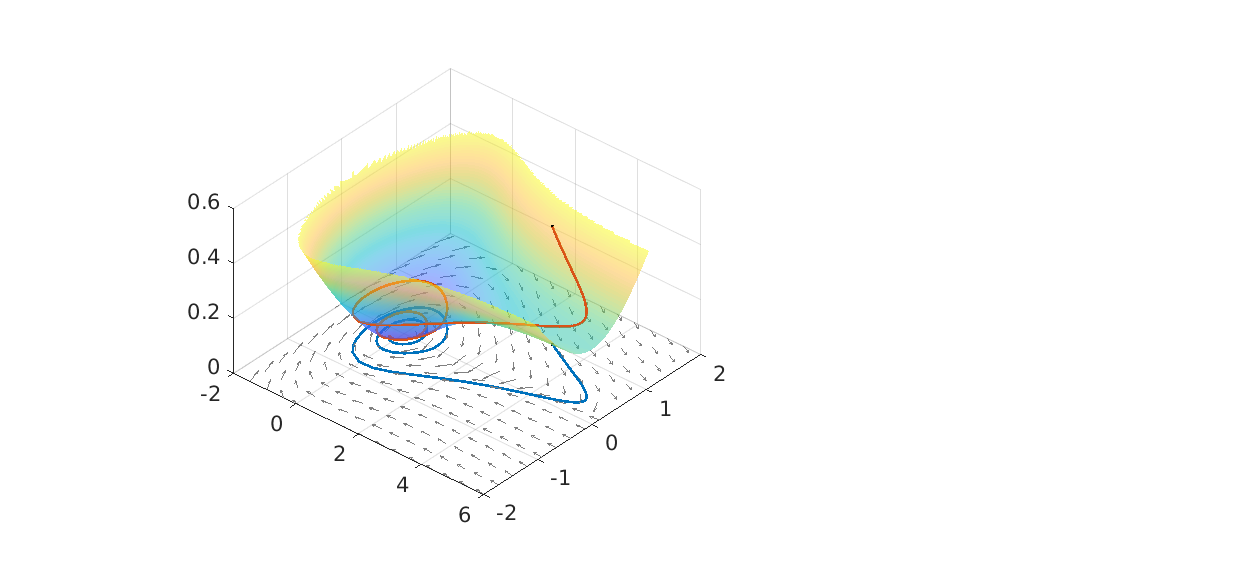

figure('Position', [ 349 368 1238 583 ]), 
subplot(1,3,[1 2])
view([ 40.9 , 34 ]), hold on, grid on
xlim([-2,6])
ylim([-2,2])
axis vis3d
plot(xx(:,1), xx(:,2),'linewidth',2)
plot(xx(1,1), xx(1,2),'.k')
plot3(xx(:,1), xx(:,2),V_xx,'linewidth',2)
plot3(xx(1,1), xx(1,2),V_xx(1),'.k')
surf(x_mesh,y_mesh,V_mesh,'facealpha',0.5)
shading interp
ax = gca;
ax.FontSize = 16;
quiver(x_mesh2,y_mesh2,v1,v2,0.5, 'Color', [1 1 1]*0.5);

## Plot2

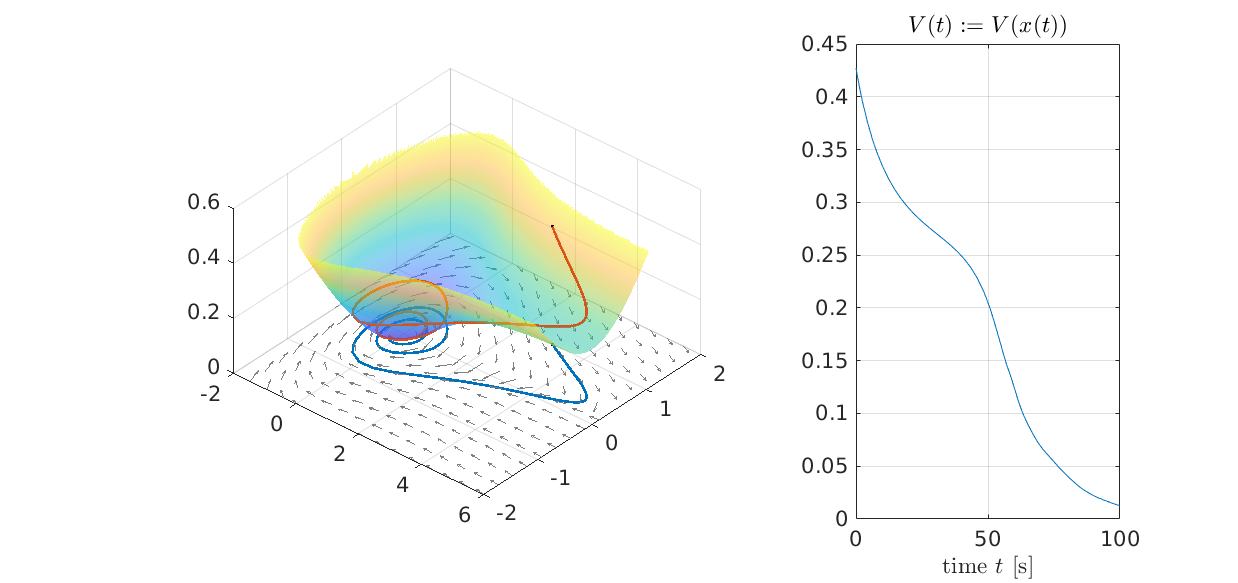

subplot(1,3,3)
plot(tt,V_xx), grid on
title('$V(t) := V(x(t))$', 'interpreter', 'latex','fontsize',22)
xlabel('time $t$ [s]', 'interpreter', 'latex','fontsize',22)
ax = gca;
ax.FontSize = 16;